# Álgebra lineal - Sistemes d'equacions

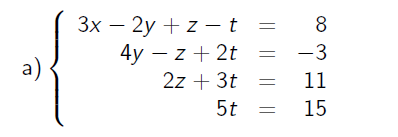

A = [3 -2 1 -1; 0 4 -1 2; 0 0 2 3; 0 0 0 5];
b = [8; -3; 11; 15];
x = backsubs(A, b)
r = A*x-b

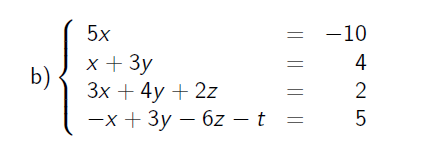

L = [5 0 0 0; 1 3 0 0; 3 4 2 0; -1 3 -6 -1];
b = [-10; 4; 2; 5];
x = forward(L, b)
r = L*x-b

## Factorització LU (Gauss) 

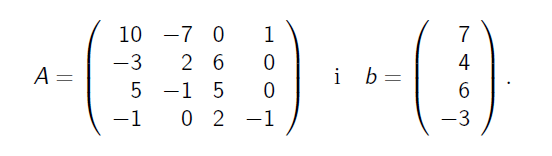

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1];
b = [7; 4; 6; -3];
[L, U] = lugui(A, 'diagonal');  %% Gauss sense pivotar
y = forward(L, b); %% pas 1
x = backsubs(U, y)  %% pas 2
r = norm(A*x-b)

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1];
b = [7; 4; 6; -3];
[L, U, p] = lutx(A);  %% Gauss pivotar parcial (agafant l'ement mes gran del col com pivot)
y = forward(L, b(p)); %% pas 1, b(p) = b amb permutant les files
x = backsubs(U, y)  %% pas 2
r = norm(A*x-b)

## Fractorització Txoleski

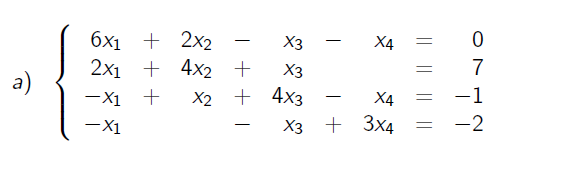

A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3];
b = [0; 7; -1; -2];
R = chol(A);  % test de simetria i definida positivament
norm(A-R'*R)

## Factorització QR

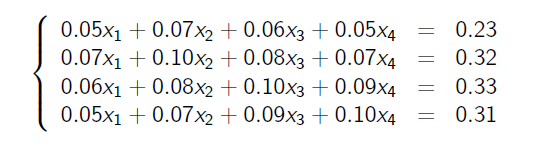

A = [0.05 0.07 0.06 0.05; 0.07 0.01 0.08 0.07; 0.06 0.08 0.1 0.09; 0.05 0.07 0.09 0.1];
b = [0.23; 0.32; 0.33; 0.31];
[R,bb] = qrsteps(A,b);
x = backsubs(R, bb);
norm(A*x-b)

ans = 1.7554e-16

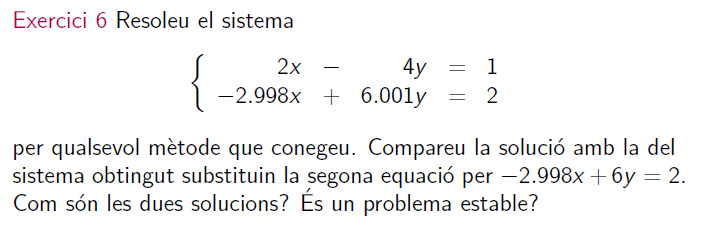

A = [2 -4; 2.998 6.001];
b = [1; 2];
%x = A\b;
x = bslashtx(A,b);
norm(A*x-b)

ans = 0

#### 6.001 => 6

AA = [2 -4; 2.998 6];
%x = A\b;
x = bslashtx(AA,b);
norm(AA*x-b)

ans = 2.2204e-16

#### Perque?

cond(A), cond(AA)

ans = 2.2681

ans = 2.2678

rcond(A), rcond(AA)

ans = 0.2666

ans = 0.2666

det(A), det(AA)

ans = 23.9940

ans = 23.9920